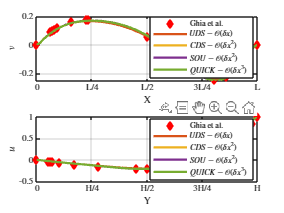

% Import data from CSV files
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');


Temporalv.v_X_UDS   =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\v_x_Re100_64_UDS.csv');
Temporalv.v_X_CDS   =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\v_x_Re100_64_CDS.csv');
Temporalv.v_X_SOU   =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\v_x_Re100_64_SOU.csv');
Temporalv.v_X_QUICK =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\v_x_Re100_64_QUICK.csv');
Temporalu.u_Y_UDS   =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\u_y_Re100_64_UDS.csv');
Temporalu.u_Y_CDS   =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\u_y_Re100_64_CDS.csv');
Temporalu.u_Y_SOU   =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\u_y_Re100_64_SOU.csv');
Temporalu.u_Y_QUICK =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\u_y_Re100_64_QUICK.csv');

[~, My_u] = size(Temporalv.v_X_CDS);
L = 1;
x_finer = linspace(0,1,My_u); 
y_finer = linspace(0,1,My_u); 

y_over_L = [1, 0.9766, 0.9688, 0.9609, 0.9531, 0.8516, 0.7344, 0.6172, 0.5, 0.4531, 0.2813, 0.1719, 0.1016, 0.0703, 0.0625, 0.0547, 0];
u_Re100 = [1, 0.84123, 0.78871, 0.73722, 0.68717, 0.23151, 0.00332, -0.13641, -0.20581, -0.2109, -0.15662, -0.1015, -0.06434, -0.04775, -0.04192, -0.03717, 0];
u_Re1000 = [1.00000, 0.65928, 0.57492, 0.51117, 0.46604, 0.33304, 0.18719, 0.05702, -0.06080, -0.10648, -0.27805, -0.38289, -0.29730, -0.22220, -0.20196, -0.18109, 0.00000];

x_over_L = [0, 0.0625, 0.0703, 0.0781, 0.0938, 0.1563, 0.2266, 0.2344, 0.5, 0.8047, 0.8594, 0.9063, 0.9453, 0.9531, 0.9609, 0.9688, 1];
v_Re100 = [0, 0.09233, 0.10091, 0.1089, 0.12317, 0.16077, 0.17507, 0.17527, 0.05454, -0.24533, -0.22445, -0.16914, -0.10313, -0.08864, -0.07391, -0.05906, 0];
v_Re1000 = [0.00000, 0.27485, 0.29012, 0.30353, 0.32627, 0.37095, 0.33075, 0.32235, 0.02526, -0.31966, -0.42665, -0.51550, -0.39188, -0.33714, -0.27669, -0.21388, 0.00000];



% For Re = 100 | Advection Schemes Comaprison
subplot(2,1,1);
scatter(x_over_L, v_Re100, 'Marker','diamond', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); hold on;
plot(x_finer, Temporalv.v_X_UDS(end, :), 'LineWidth', 2); 
plot(x_finer, Temporalv.v_X_CDS(end, :), 'LineWidth', 2); 
plot(x_finer, Temporalv.v_X_SOU(end, :), 'LineWidth', 2); 
plot(x_finer, Temporalv.v_X_QUICK(end, :), 'LineWidth', 2); grid on; box on;
ylabel('$\textit{v(x)}$');
legend({'Ghia et al.','$UDS - \mathcal{O}(\delta x)  $', '$CDS - \mathcal{O}(\delta x^{2}) $','$SOU - \mathcal{O}(\delta x^{2})  $','$QUICK - \mathcal{O}(\delta x^{3})  $'}, 'Location', 'Best');

xticks([0, L/4, L/2, 3*L/4, L]); 
xlabel('X'); ylabel('$v$');
% Label the tick marks
xticklabels({'0', 'L/4', 'L/2', '3L/4', 'L'});




subplot(2,1,2);
scatter(y_over_L, u_Re100, 'Marker','diamond', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); hold on;
plot(x_finer, Temporalu.u_Y_UDS(end, :), 'LineWidth', 2); 
plot(x_finer, Temporalu.u_Y_CDS(end, :), 'LineWidth', 2); 
plot(x_finer, Temporalu.u_Y_SOU(end, :), 'LineWidth', 2); 
plot(x_finer, Temporalu.u_Y_QUICK(end, :), 'LineWidth', 2); grid on; box on;
ylabel('$\textit{u(y)}$');
legend({'Ghia et al.','$UDS - \mathcal{O}(\delta x)  $', '$CDS - \mathcal{O}(\delta x^{2}) $','$SOU - \mathcal{O}(\delta x^{2})  $','$QUICK - \mathcal{O}(\delta x^{3})  $'}, 'Location', 'Best');

xticks([0, L/4, L/2, 3*L/4, L]); 
xlabel('Y'); ylabel('$u$');
% Label the tick marks
xticklabels({'0', 'H/4', 'H/2', '3H/4', 'H'});